# Using Euler, Euler-Cromer, and Huen with Harmonic Oscillator. 

## Learning Goals: 

- Learn about finite differences in 2nd order differential equations

- Practice the use of a for loop

- Learn about inaccuracies in solving differential equations numerically   

## The Physics 

 
$$m\frac{d^2 x}{d t^2} = F(x,v,t) = -k x \,\, \Rightarrow$$



$$\frac{d^2 x}{d t^2} = a = -\omega^{2} x$$


where 

$a(x,v,t) = \frac{F(x,v,t)}{m}$ is the acceleration and $\omega = \frac{2\pi}{T} = \sqrt{\frac{k}{m}}$ is the angular frequency. 

We will take $T = 1$s, which sets the angular frequency. We will also use mass is $m = 1$ kg . This will be needed to calculate the energy. These two values set $k$.  

## Finite Difference Approach  

in all cases 

$v_{i+1} = v_i + a(x_i,v_i,t_i) dt$. 

There are different approaches to calculating the position.  

%set(0,'defaultTextInterpreter','latex');

mass = 1 ; % kg
T = 1; 

om = 2*pi/T % rad/s, angular frequency in seconds and frequency

om = 6.2832

omsq = om^2  % (rad/s)^2, omega squared

omsq = 39.4784

k = mass*omsq  % N/m, spring constant

k = 39.4784


nelements = 5000; % set the number of points 
% in the time, velocity, and position arrays
itime = 0; % s, initial time
ftime = 5; % s, final time. It will give five periods. 

ivel = 0; % m/s, initial velocity
ipos = 1; % m, initial position

time = linspace(itime,ftime,nelements) ; %Linearly space array
% row vector of times
time = time' ; % make it a column vector
dt = time(2)-time(1) ; % Find dt. 

% pre-allocate memories for x,v and t arrays to improve performance. 
% Otherwise matlab changes the size of each array 
% dynamically, which is slow. 
% set x,v as single precision column vectors with zeros
x = zeros(nelements,1,'single'); % position
v = zeros(nelements,1,'single'); % velocity 

% Set the initial condition for the first element of x
% The initial condition for v is already set (=0)
x(1,1) = ipos;

disp('end of section 1')

end of section 1


% Euler method 

for i = 1:nelements-1 
    % End when i = N-1 is calculated. Otherwise we will
    % get arrays with 1001 elements
    v(i+1,1) = v(i,1) - omsq*x(i,1)*dt ;
    x(i+1,1) = x(i,1) + v(i,1)*dt ;
end % end the for loop

E = (1/2).*(mass.*v.^(2) + k.*x.^(2) ) ; % calculate the energy

disp('end of section 2')

end of section 2


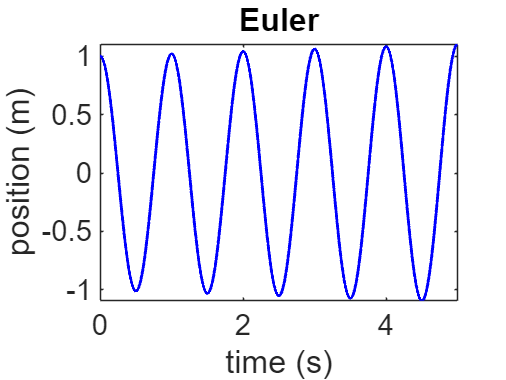

% Plot the results

plot(time,x,'-b','LineWidth',2)
title('Euler')
set(gca,'fontsize',20)
xlabel('time (s)')
ylabel('position (m)')
%xticks(linspace(0,2,5))
xlim([0 5])

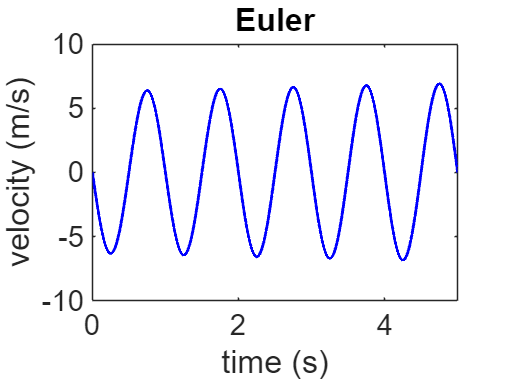

%ylim([0.0 9.0])
%legend('cosh','parabolic','Box','off')

plot(time,v,'-b','LineWidth',2)
title('Euler')
set(gca,'fontsize',20)
xlabel('time (s)')
ylabel('velocity (m/s)')
%xticks(linspace(0,2,5))
xlim([0 5])

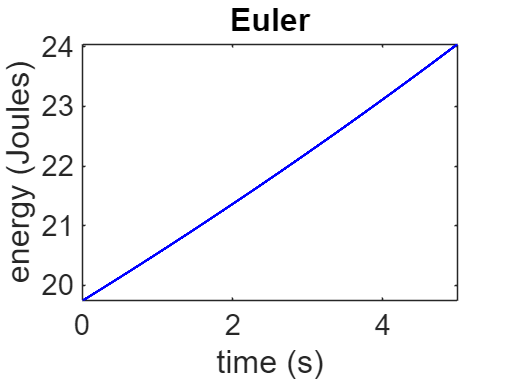

%yticks(linspace(-8,8,5))
%ylim([-8 8])

plot(time,E,'-b','LineWidth',2)
title('Euler')
set(gca,'fontsize',20)
xlabel('time (s)')
ylabel('energy (Joules)')
%xticks(linspace(0,2,5))
xlim([0 5])

%ylim([19.6 20.2])


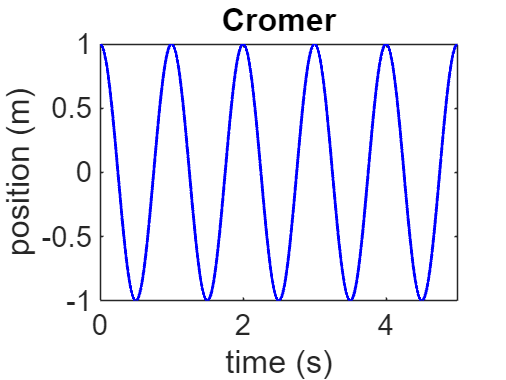


% Euler - Cromer method

% re-initialize the arrays, we before
x = zeros(nelements,1,'single'); 
v = zeros(nelements,1,'single');

% Set the initial condition for the first element of x
% The initial condition for v is already set (=0)
x(1,1) = ipos;

for i = 1:nelements-1  % 
    v(i+1,1) = v(i,1) - omsq*x(i,1)*dt;
    x(i+1,1) = x(i,1) + v(i+1,1)*dt;
end % 

E = (1/2)*(mass*v.^2+k*x.^2) ;

%plot(x,v,'-b',x,para,'-r','LineWidth',2)
plot(time,x,'-b','LineWidth',2)
title('Cromer')
set(gca,'fontsize',20)
xlabel('time (s)')
ylabel('position (m)')
%xticks(linspace(0,2,5))
xlim([0 5])

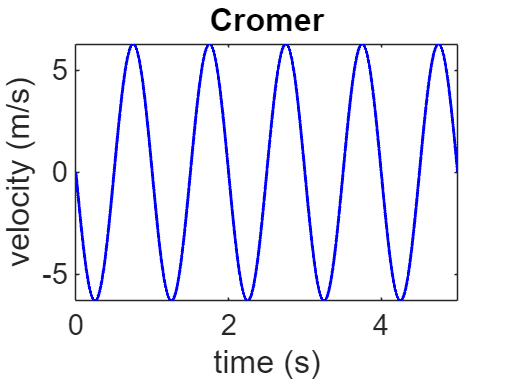

%ylim([0.0 9.0])

plot(time,v,'-b','LineWidth',2)
title('Cromer')
set(gca,'fontsize',20)
xlabel('time (s)')
ylabel('velocity (m/s)')
%xticks(linspace(0,2,5))
xlim([0 5])

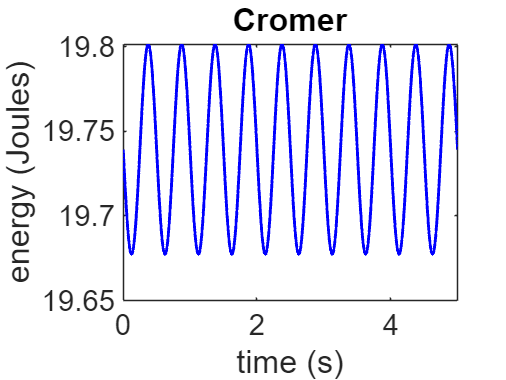

%yticks(linspace(-8,8,5))
%ylim([-8 8])

plot(time,E,'-b','LineWidth',2)
title('Cromer')
set(gca,'fontsize',20)
xlabel('time (s)')
ylabel('energy (Joules)')
%xticks(linspace(0,2,5))
xlim([0 5])

%ylim([19.6 20.2])


**1.** Changing the time step results in Euler's non-convservation of energy increasing by a lot. I changed time steps form 5000 to 500 and it changed the energy gain from around 25 Joules to around 150. Cromer's method is unchanged in terms of energy.

**2.** Heun's method. *Heuns method calculates the averages and then adds, it is like a combination of Euler's  and Cromer's method.*

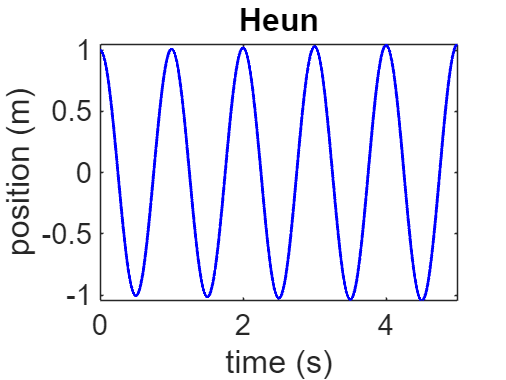

for i = 1:nelements-1
    v(i+1,1) = v(i,1) - omsq*x(i,1)*dt ;
    v_avg = (1/2)*(v(i,1)+v(i+1,1)) ;
    x(i+1,1) = x(i,1) + v_avg*dt ;
end
E = (1/2)*(mass*v.^2+k*x.^2) ;

%plot(x,v,'-b',x,para,'-r','LineWidth',2)
plot(time,x,'-b','LineWidth',2)
title('Heun')
set(gca,'fontsize',20)
xlabel('time (s)')
ylabel('position (m)')
%xticks(linspace(0,2,5))
xlim([0 5])

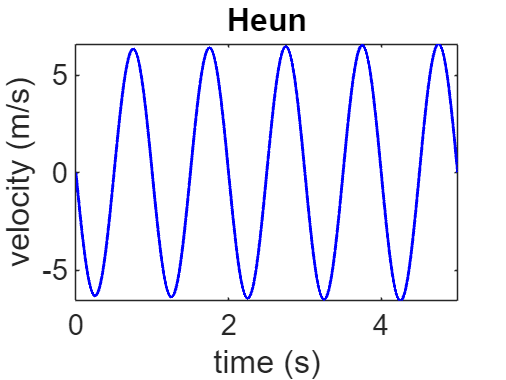

%ylim([0.0 9.0])

plot(time,v,'-b','LineWidth',2)
title('Heun')
set(gca,'fontsize',20)
xlabel('time (s)')
ylabel('velocity (m/s)')
%xticks(linspace(0,2,5))
xlim([0 5])

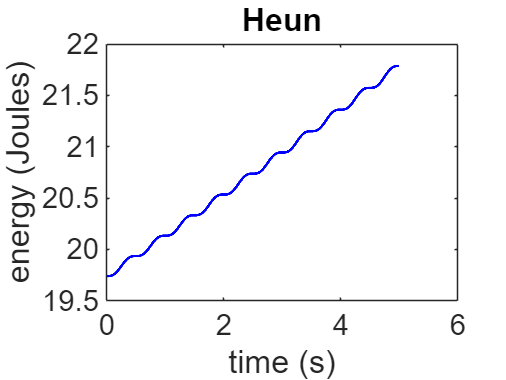

%yticks(linspace(-8,8,5))
%ylim([-8 8])

plot(time,E,'-b','LineWidth',2)
title('Heun')
set(gca,'fontsize',20)
xlabel('time (s)')
ylabel('energy (Joules)')

%xticks(linspace(0,2,5))
%xlim([0 5])
%ylim([19.6 20.2])

**2. **Using Heun's method the energy conservation is a combination of Cromer's method and Euler's method with it being a linear line with a slight wobble like it is oscillating.

**3.** Use ode45

Formula:


$$\frac{d^2 x}{d t^2} = a = -\omega^{2} x$$


% Matlab ode45
disp(omsq)

   39.4784



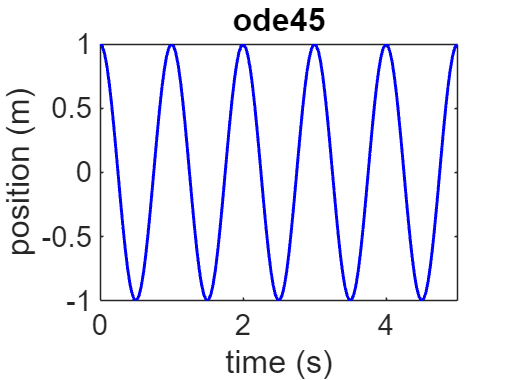

function xdot = odefun(t, x, omsq)
    xdot(1) = x(2) ;
    xdot(2) = - omsq*x(1) ;
    xdot = xdot' ;
end
tspan = [itime, ftime] ;
[t, x] = ode45(@(t, x)odefun(t, x, omsq), tspan, [ipos, ivel]) ;

E = (1/2)*(mass*x(:, 2).^2+k*x(:, 1).^2) ;

%plot(x,v,'-b',x,para,'-r','LineWidth',2)
plot(t,x(:, 1),'-b','LineWidth',2)
title('ode45')
set(gca,'fontsize',20)
xlabel('time (s)')
ylabel('position (m)')
%xticks(linspace(0,2,5))
xlim([0 5])

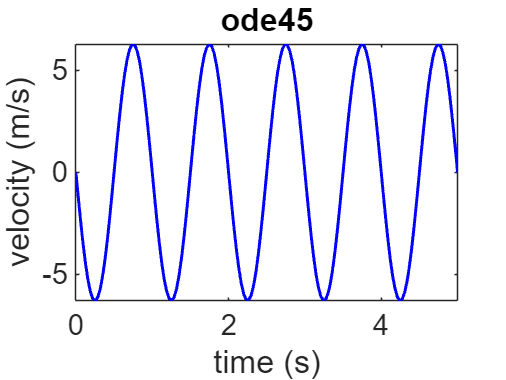

%ylim([0.0 9.0])

plot(t,x(:, 2),'-b','LineWidth',2)
title('ode45')
set(gca,'fontsize',20)
xlabel('time (s)')
ylabel('velocity (m/s)')
%xticks(linspace(0,2,5))
xlim([0 5])

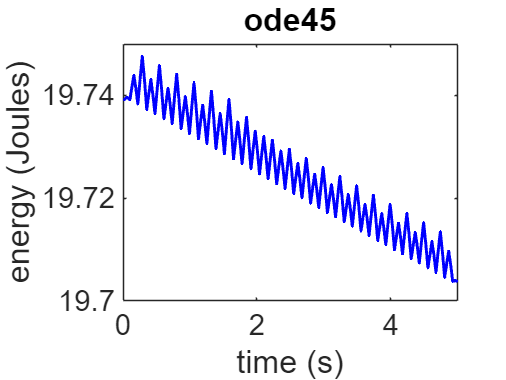

%yticks(linspace(-8,8,5))
%ylim([-8 8])

plot(t,E,'-b','LineWidth',2)
title('ode45')
set(gca,'fontsize',20)
xlabel('time (s)')
ylabel('energy (Joules)')
%xticks(linspace(0,2,5))
xlim([0 5])

%ylim([19.6 20.2])

**4.** The energy non-conservation is similar to Heun's but flipped with total overall energy going down. It is odd that it is decreasing as there is no friction. It is also important to not the decrease in energy we see here is in a much smaller range (~0.4 J) than the other methods.

**5.**

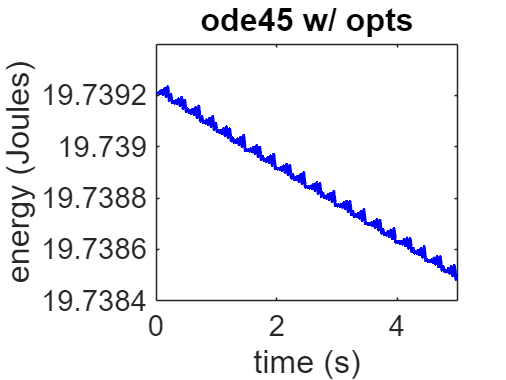

opts = odeset('RelTol',1e-5,'AbsTol',1e-6) ;
[t, x] = ode45(@(t, x)odefun(t, x, omsq), tspan, [ipos, ivel], opts) ;

E = (1/2)*(mass*x(:, 2).^2+k*x(:, 1).^2) ;

plot(t,E,'-b','LineWidth',2)
title('ode45 w/ opts')
set(gca,'fontsize',20)
xlabel('time (s)')
ylabel('energy (Joules)')
%xticks(linspace(0,2,5))
xlim([0 5])

%ylim([19.6 20.2])

**6. **

**RelTol - **This option means 'relative tolerance error' which controls the number of correct digits in each of ode45's solutions / at each step. This is determined by a calculation or local error that MatLab does at each point. With a value of 1e-5 any decimal point past 1e-5 will be cut off but will not effect the output it the calculated correct digits is before the 1e-5 digit.

**AbsTol - **This option means 'absolute tolerance error' which controls the absolute number of digits no matter if they are 'correct' or not. With a value of 1e-6, any digit beyond 1e-6 in the solutions will not be recorded no matter what

RelTol default, (1e-3)

AbsTol default, (1e-6)

Applying the opts variable does not change AbsTol by anything but gives more digits to work with as RelTol is decreased.